## User Input Params

%mmc_rms_curr_approx_eq = "steve_mcconner";
mmc_rms_curr_approx_eq = "mujoe";

## Compute Derived Params

% Compute capacitance of primary tank to achieve resonant frequency of
% secondary tank circuit, given primary coil inductance
C_pri_tank_target = ((1/(2*pi*SYSTEM.F_res_pri))^2)*(1/PRI_TANK.Lp);


% Primary tank surge impedance should be at least 10x bridge output
% impedance
Min_primary_tank_surge_impedance = INVERTER.Zout * 10;

Pri_tank_surge_impedance = computePrimaryImpedance(PRI_TANK.Lp,C_pri_tank_target);

if Pri_tank_surge_impedance < Min_primary_tank_surge_impedance
    warning("Primary tank surge impedance lower then recommended minimum: %0.2f < %0.2f Ohm",Pri_tank_surge_impedance,Min_primary_tank_surge_impedance);
end

## MMC Bank Computation

% Compute MMC bank reactance
MMC_bank_Xc = 1 / (2 * pi * SYSTEM.F_res_pri * C_pri_tank_target); 

% Compute approximate peak voltage seen by MMC capacitor bank, 
% assuming 0 ESR for now 
MMC_pk_v_approx = MMC_bank_Xc * INVERTER.OCP_limit;  % V


if MMC_BANK.Ns == -1
    % Compute min number of capacitors in series to accomodate this peak
    % voltage, per parallel branch
    MMC_BANK.Ns = ceil(MMC_pk_v_approx/MMC_BANK.Cap_VDC_rating);
end

if MMC_BANK.Np == -1
    % Compute min number of capacitor parallel branches to handle peak current
    MMC_BANK.Np = ceil(SYSTEM.OCD_max/MMC_BANK.Cap_Ipk_rating);
end

MMC_total_cap_N = MMC_BANK.Np * MMC_BANK.Ns;  % Total number of capacitors within MMC bank

% Compute ESR of MMC bank, Ohm
MMC_BANK.Bank_ESR = (MMC_BANK.Ns*MMC_BANK.Cap_ESR)/MMC_BANK.Np; 

% Compute the total capacitance of the MMC bank
MMC_BANK.Cap_bank = (MMC_BANK.Cap/MMC_BANK.Ns)*MMC_BANK.Np; % F

% Compute the percent error of the MMC bank total capacitance
MMC_bank_cap_pe = (abs(MMC_BANK.Cap_bank-C_pri_tank_target)/C_pri_tank_target)*100;



#### Compute actual MMC Bank Parameters

[Source](https://kaizerpowerelectronics.dk/calculators/mmc-calculator/)

% Compute the VDC rating of the MMC bank
MMC_BANK.Bank_VDC_rating = MMC_BANK.Cap_VDC_rating * MMC_BANK.Ns;  % V

% Compute actual primary resonant frequency with MMC bank
f_res_pri_actual = 1/(2*pi*sqrt(MMC_BANK.Cap_bank*PRI_TANK.Lp)); % Hz

% Primary tank resonant freq percent error
f_res_pri_pe = (abs(f_res_pri_actual-SYSTEM.F_res_pri)/SYSTEM.F_res_pri)*100; % %
% Actual primary tank surge impedance
Pri_tank_surge_impedance_actual = computePrimaryImpedance(PRI_TANK.Lp,MMC_BANK.Cap_bank); % Ohm

% Compute actual MMC bank reactance
MMC_bank_Xc_actual = 1 / (2 * pi * f_res_pri_actual * MMC_BANK.Cap_bank); % F

% Compute actual impedance of MMC bank
Z_mmc_bank_actual = sqrt(MMC_BANK.Bank_ESR^2 + MMC_bank_Xc_actual^2);    % Ohms

% Quality factor of MMC bank
Q_factor_mmc_bank = MMC_bank_Xc_actual/MMC_BANK.Bank_ESR;

% Compute peak voltage seen by MMC capacitor bank,
MMC_bank_pk_v= Z_mmc_bank_actual * INVERTER.OCP_limit;  % V

% Compute peak current rating of MMC bank, A
MMC_BANK.Bank_Ipk_rating = MMC_BANK.Cap_Ipk_rating * MMC_BANK.Np;

if MMC_bank_pk_v >= MMC_BANK.Bank_VDC_rating
    warning("Peak voltage seen by MMC bank exceeds voltage rating: %0.2f >= %0.2f kV", MMC_bank_pk_v/1e3, MMC_BANK.Bank_VDC_rating/1e3);
end

% Peak current seen by MMC bank, A
Ipk_mmc_bank = INVERTER.OCP_limit;

if Ipk_mmc_bank >= MMC_BANK.Bank_Ipk_rating
    warning("Peak current seen by MMC bank exceeds rating: %0.2f >= %0.2f Apk", Ipk_mmc_bank, MMC_BANK.Bank_Ipk_rating);
end

switch mmc_rms_curr_approx_eq
    case "steve_mcconner"
        % Compute RMS current through MMC bank in worst-case conditions: max PRF
        % frequency and max duty cycle
        Irms_mmc_bank = 0.5 * Ipk_mmc_bank * sqrt(SYSTEM.PRF_Ton_max*SYSTEM.PRF_fmax); % Arms
    case "mujoe"
        drsstc.Lp = PRI_TANK.Lp;
        drsstc.Vbus = INVERTER.Vbus;
        % Delay between OCD trip event and actual inverter shutdown (sec)
        drsstc.t_d = 0; 
        epsil = 0.01;   % 1 % of I_ocd
        f_prf = SYSTEM.PRF_fmax;    % Hz
        DC_prf = SYSTEM.PRF_DC_max;     % %
        ocd_lim = SYSTEM.OCD_max;  % A
        % Phase mismatch between primary current and inverter output
        % voltage
        phase_err_rad = 0; % rad
        % Primary current loop total parasitic resistance
        R_eq = 0.0748; % Ohm
        prf_on_time = (DC_prf/100)*(1/f_prf); % sec
        Irms_mmc_bank = approx_mmc_rms_current(f_prf, prf_on_time, ocd_lim, phase_err_rad, R_eq, epsil, drsstc);
    otherwise
        error("Invalid MMC RMS Current Approx. Equation: %s",mmc_rms_curr_approx_eq);
end

% dV/dt seen by MMC bank for given circuit conditions
MMC_bank_dvdt = 2*pi*MMC_bank_pk_v*f_res_pri_actual;  % V/s

% Compute the dV/dt rating of the MMC bank
% Using i = C*dV/dt -> dV/dt = i/C where i is the peak current rating of
% the bank and C is the MMC bank capacitance
MMC_BANK.Bank_dVdt_rating = MMC_BANK.Bank_Ipk_rating/MMC_BANK.Cap_bank; % V/s

if MMC_bank_dvdt >= MMC_BANK.Bank_dVdt_rating
     warning("Max dV/dt of MMC bank exceeded: %0.2f >= %0.2f V/usec", MMC_bank_dvdt/1e6, MMC_BANK.Bank_dVdt_rating/1e6);
end

% Compute total power dissapated by each capacitor in bank
Irms_per_branch = Irms_mmc_bank/MMC_BANK.Np;

% Compute reactance of single capacitor
MMC_cap_Xc = 1 / (2 * pi * f_res_pri_actual * MMC_BANK.Cap);  % Ohms

% Compute impedance of single capacitor
Z_mmc_cap = sqrt((MMC_BANK.Cap_ESR^2) + (MMC_cap_Xc^2));   % Ohms

% Compute power dissapated by each capacitor
P_dis_mmc_cap = (Irms_per_branch^2)*MMC_BANK.Cap_ESR; % W

% Compute temperature rise for each capacitor
Trise_mmc_cap = MMC_BANK.Cap_Rth*P_dis_mmc_cap;      % Celsius

% Compute the temperature of individual capacitor 
T_mmc_cap = SYSTEM.Tc_ambient + Trise_mmc_cap;         % Celsius

if T_mmc_cap > MMC_BANK.Cap_Tc_max
    warning("MMC capacitor temperature range exceeded: %0.1f > %0.1f C",T_mmc_cap, MMC_BANK.Cap_Tc_max)
end


#### Compute MMC Energy

[Source](https://kaizerpowerelectronics.dk/tesla-coils/drsstc-design-guide/dc-bus-capacitor/)

This seems incorrect, not sure where 1/pi parameter comes from.

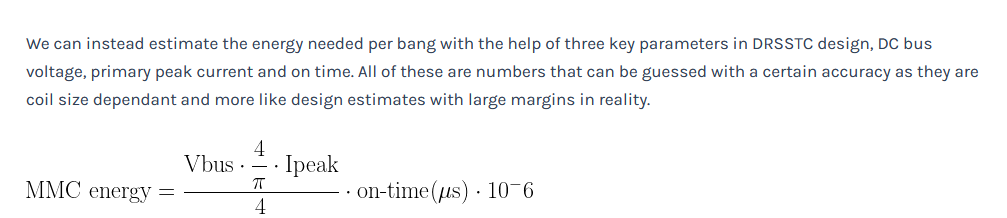

What this user said in the comments makes more sense, and it is the equation that we will use.

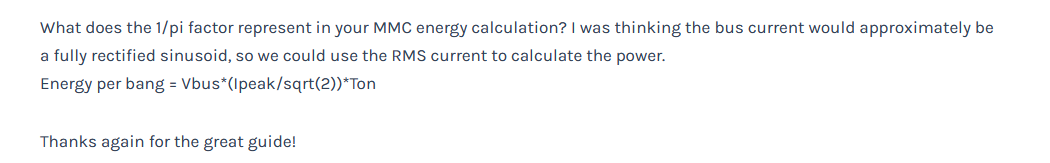


% Compute required energy to be stored in MMC bank under worse-case
% conditions: max PRF frequency and max PRF duty cycle (e.g. max on-time)
% for each bang (e.g. 1 PRF cycle)
MMC_BANK.Bank_bangEnergy = INVERTER.Vbus*(INVERTER.OCP_limit/sqrt(2))*SYSTEM.PRF_Ton_max; % Joules


## Print Results

fprintf("\n\n################ Primary tank Params BEGIN ##########################\n\n")
fprintf("Primary coil inductance: %0.4f nH\n\n", PRI_TANK.Lp*1e9);
fprintf("Min primary tank surge impedance: %0.2f Ohm\n\n", Min_primary_tank_surge_impedance);
fprintf("MMC bank target capacitance: %0.4f uF\n\n", C_pri_tank_target*1e6);
fprintf("MMC bank capacitance: %0.4f uF (target: %0.4f uF, error: %0.2f %%)\n\n", MMC_BANK.Cap_bank*1e6,C_pri_tank_target*1e6,MMC_bank_cap_pe);
fprintf("MMC bank VDC rating: %0.2f kVDC\n\n", MMC_BANK.Bank_VDC_rating/1e3);
fprintf("MMC bank Ipk rating: %0.2f Apk\n\n", MMC_BANK.Bank_Ipk_rating);
fprintf("MMC bank dV/dt rating: %0.0f V/usec\n\n", MMC_BANK.Bank_dVdt_rating/1e6);
fprintf("MMC bank impedance magnitude: %0.2f Ohm\n\n", Z_mmc_bank_actual);
fprintf("MMC bank Q factor: %0.2f\n\n", Q_factor_mmc_bank);
fprintf("Actual primary resonant frequency: %0.2f kHz (error: %0.2f %%)\n\n", f_res_pri_actual/1e3, f_res_pri_pe);
fprintf("Peak voltage seen by MMC bank: %0.2f kV\n\n", MMC_bank_pk_v/1e3);
fprintf("dV/dt seen by MMC bank: %0.0f V/usec\n\n", MMC_bank_dvdt/1e6);
fprintf("RMS current seen by MMC bank: %0.2f A\n\n", Irms_mmc_bank);
fprintf("Power dissapated by each cap: %0.2f W\n\n", P_dis_mmc_cap);
fprintf("Temperature rise above ambient for each cap: %0.2f C\n\n", Trise_mmc_cap);
fprintf("Final temperature for each cap: %0.2f C\n\n", T_mmc_cap);

fprintf("MMC bank # of capacitors: %d parallel branches w/ %d in series per branch (%d total)\n\n", MMC_BANK.Np, MMC_BANK.Ns,MMC_total_cap_N);
fprintf("MMC bank total price: %0.2f (USD)\n\n", MMC_total_cap_N*MMC_BANK.Cap_price);
fprintf("################ Primary tank Params END ##########################\n\n")